# Sample 6-6

## 標本化

二変量アップサンプリング

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Sampling

Bivariate upsampling

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### 可分離間補間行列の設定

(Setting a separable upsampling factor)

- $\mathbf{M}$: 補間行列 (upsampling factor)

 可分離の場合 (In the separable case)

        
$$\mathbf{M}=\left(\begin{array}{cc} M_1 & 0 \\ 0 & M_2 \end{array}\right)\in \mathbb{Z}^{2\times 2}$$


% Vertical upsampling ratio
verticalUFactor = 2; 
% Horizontal upsampling factor
horizontalUFactor = 3; 

### 入力配列の設定

(Setting an input array)

- $\{u[\mathbf{n}]\}_\mathbf{n}$: 入力配列 (input array)

% Standard deviation 
sigma = 2;
% Array size
sizeU = 31;

% Generate an array with bivariate Gaussian function
arrayU = fspecial('gaussian',sizeU,sigma);

### 入力配列のスペクトル

(Spectrum of the input array)

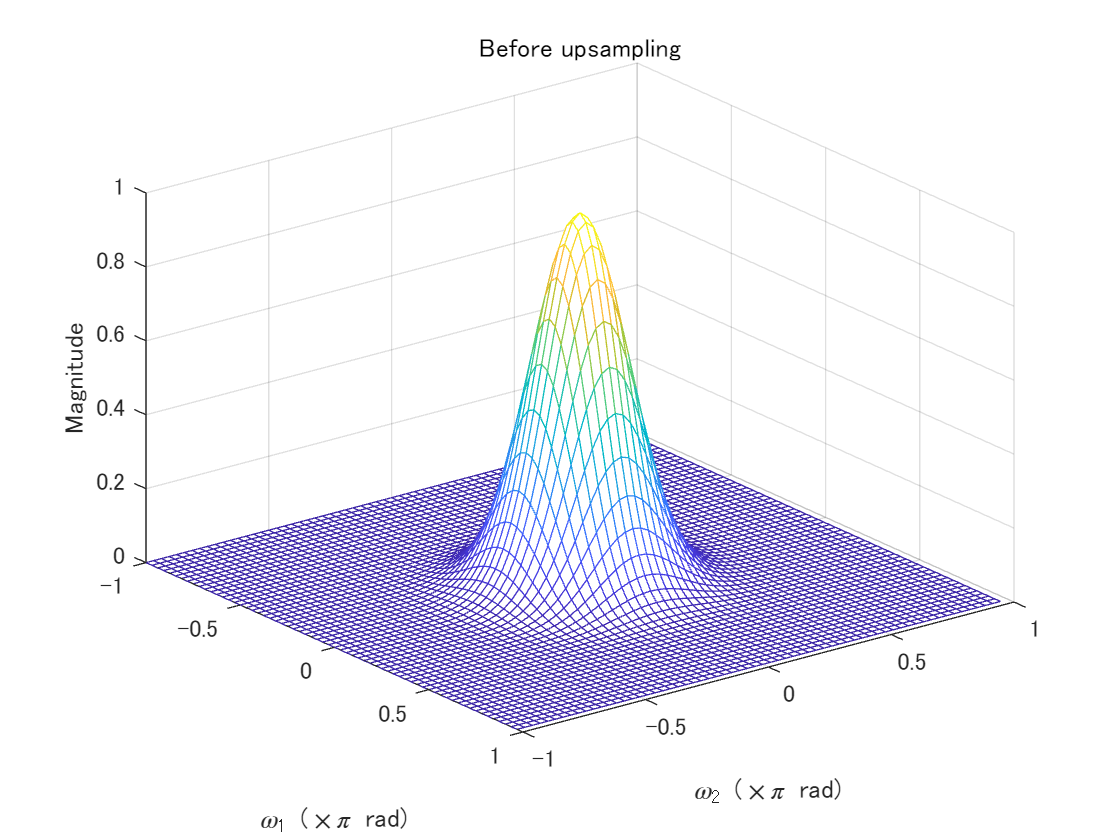

% Spectrum of u[n]
figure(1)
freqz2(arrayU)
xlabel('\omega_2 (\times\pi rad)')
ylabel('\omega_1 (\times\pi rad)')
title('Before upsampling')
axis ij

### 出力配列の計算

(Computation of the output array)

- $\{v[\mathbf{m}]\}_\mathbf{m}$: 出力数列 (output sequence)

        
$$v[\mathbf{m}] = \left\{\begin{array}{ll}  u[\mathbf{M}^{-1}\mathbf{m}] & \mathbf{m}\in\mathcal{L}(\mathbf{M}) \\ 0 &\mathrm{otherwise} \\ \end{array}\right.$$


        
$$\mathcal{L}(\mathbf{M})\colon = \{\mathbf{Mk} | \mathbf{k}\in\mathbb{Z}^2\}$$


% Definition of bivariate separable upsampling
upsample2 = @(x,n) ...
    shiftdim(upsample(...
    shiftdim(upsample(x,...
    n(1)),1),...
    n(2)),1);

% Bivariate separable upampling
arrayV = upsample2(arrayU, [verticalUFactor horizontalUFactor]);

### 出力配列のスペクトル

(Spectrum of the output array)

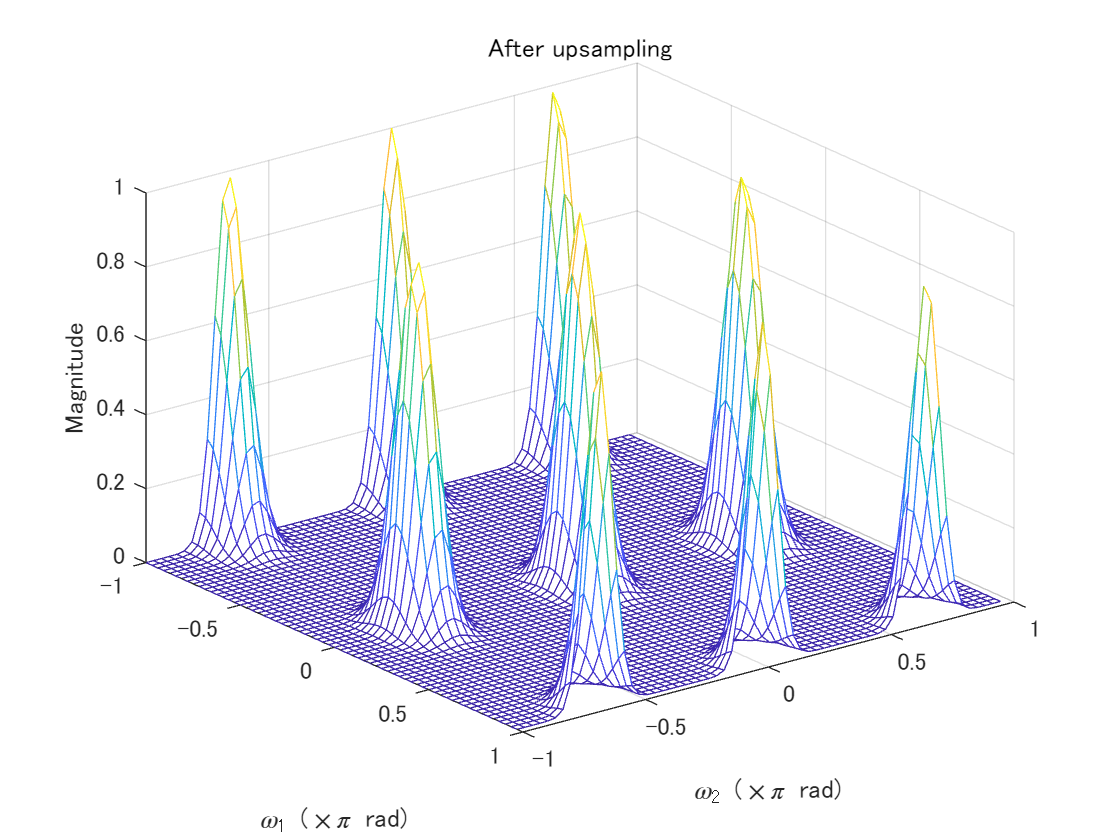

figure(2)
freqz2(arrayV)
xlabel('\omega_2 (\times\pi rad)')
ylabel('\omega_1 (\times\pi rad)')
title('After upsampling')
axis ij

### 非可分補間行列の設定

(Setting a non-separable upsampling factor)

- $\mathbf{M}$: 補間行列 (upsampling factor)

 一般的な場合 (In the general case)

        
$$\mathbf{M}=\left(\begin{array}{cc} \mathbf{m}_{1} & \mathbf{m}_{2} \end{array}\right)\in \mathbb{Z}^{2\times 2}$$


% Upsampling factor
upMtx = [ 1 1 ; -1 1 ];

### 入力配列の設定

(Setting an input array)

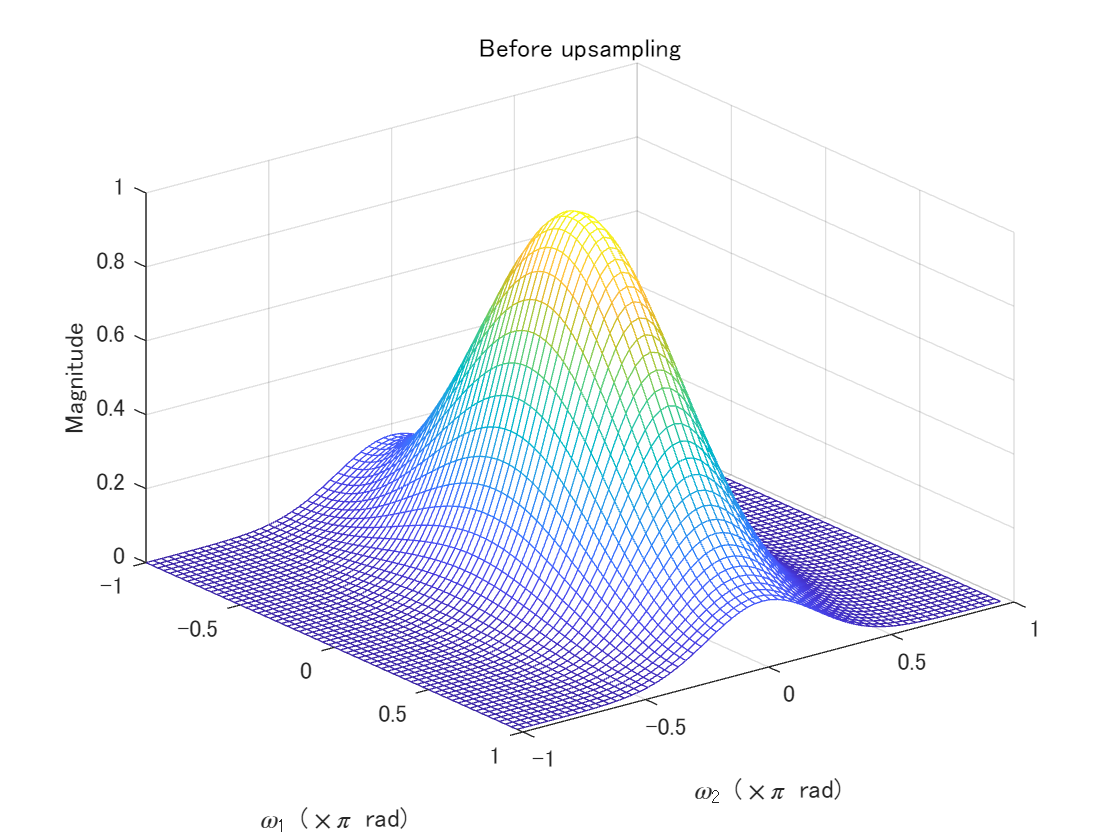

% Covariance matrix
covMtx  = [2 0 ; 0 1/2];
% Array size
sizeU = 31;

% Generate an array with bivariate Gaussian function
arrayU = mygaussian2(sizeU,covMtx);

% Spectrum of u[n]
figure(3)
freqz2(arrayU)
xlabel('\omega_2 (\times\pi rad)')
ylabel('\omega_1 (\times\pi rad)')
title('Before upsampling')
axis ij

### 出力配列の計算

(Computation of the output array)

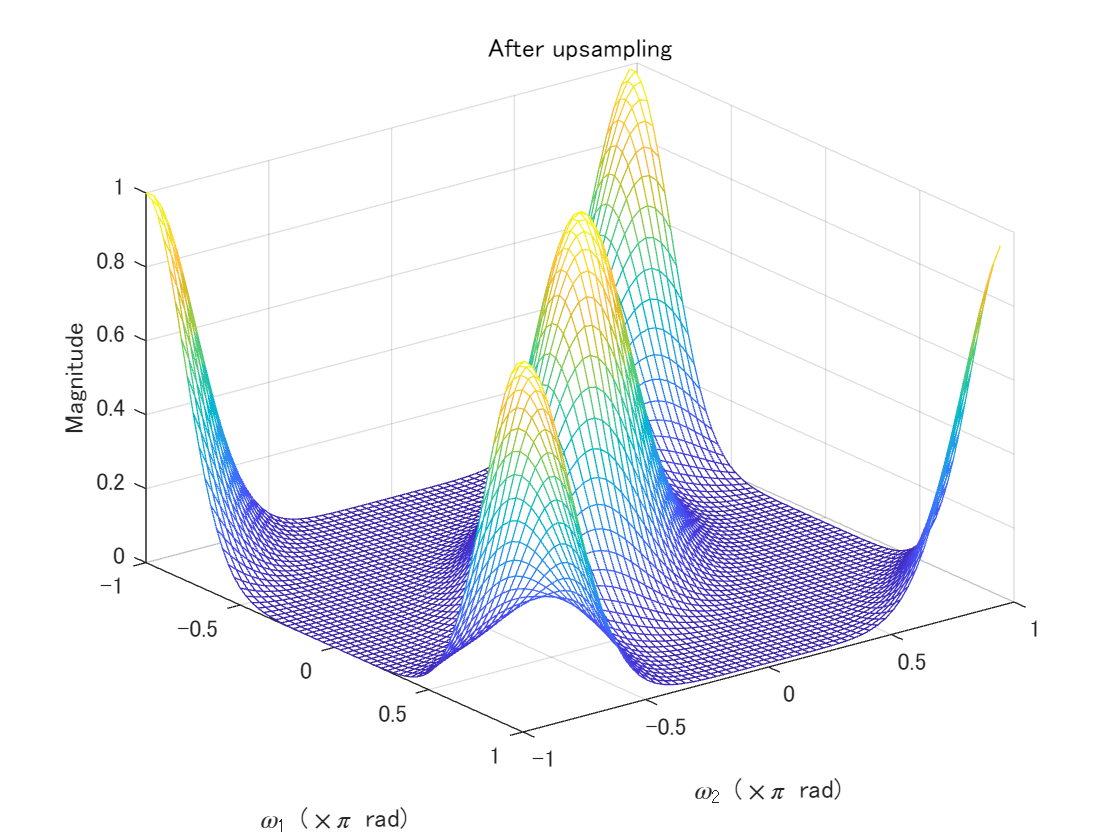

% Bivariate non-separable upsampling
arrayV = myupsample2(arrayU,upMtx);

% Spectrum of v[m]
figure(4)
freqz2(arrayV)
xlabel('\omega_2 (\times\pi rad)')
ylabel('\omega_1 (\times\pi rad)')
title('After upsampling')
axis ij

### プライベート関数の定義

(Definitions of private functions)

二変量ガウス配列の生成関数　(Generation function of bivariate Gaussian arrays)

function x = mygaussian2(sizeX, covMtx)
% MYGAUSSIAN2
%
% Inputs
%
%   sizeX: size of output array 
%   covMtx: covariance matrix
%
% Output
%
%   x: array generated by Gauss Func. 
%
sizeHalf = floor(sizeX / 2);

if isscalar(covMtx)
    covMtx = covMtx * eye(2);
end

x = zeros(sizeHalf*2);
iRow = 1;
for n1 = -sizeHalf:sizeHalf
    iCol = 1;
    for n0 = -sizeHalf:sizeHalf    
        p = - 0.5 * [ n0 n1 ] * (covMtx\[ n0 n1 ].');
        x(iRow,iCol) = exp(p);
        iCol = iCol + 1;
    end
    iRow = iRow + 1;
end
x = x / sum(sum(x));

end % of mygaussian2

二変量非可分アップサンプリング関数 (bivariate non-separable upsampling function)

function [outputArray, X, Y] = myupsample2(inputArray,upMtx)
% MYUPSAMPLE2
%
% Inputs
%
%   inputArray: input array
%   upMtx: upsampling matrix
%
% Outputs
%
%   outputArray: output array 
%   X          : horizontal sampling points
%   Y          : vertical sampling points
%

% Size of input array
nRowsInputArray = size(inputArray,1);
nColsInputArray = size(inputArray,2);
nCompInputArray = size(inputArray,3);

% Calculation of the support region after upsampling
vertexPoints(:,1) = [ 0 0 ].';
vertexPoints(:,2) = upMtx * [ 0 nColsInputArray ].';
vertexPoints(:,3) = upMtx * [ nRowsInputArray 0 ].';
vertexPoints(:,4) = upMtx * [ nRowsInputArray nColsInputArray ].';
minPoint = floor(min(vertexPoints,[],2));
maxPoint = ceil(max(vertexPoints,[],2))-1;

% Upsampling
clear arrayY
iRow = 1;
for m0 = minPoint(1):maxPoint(1)
    iCol = 1;
    for m1 = minPoint(2):maxPoint(2)
        outputArray(iRow, iCol, :) = zeros(1,nCompInputArray,...
                'like',inputArray);        
        originalPoint = upMtx \ [ m0 m1 ].';
        lat = upMtx * fix(originalPoint);
        if m0 == lat(1) && m1 == lat(2)
            n0 = originalPoint(1);
            n1 = originalPoint(2);
            if n0 >= 0 && n0 < nRowsInputArray  && ...
                n1 >= 0 && n1< nColsInputArray
                outputArray(iRow, iCol, :) = inputArray(n0 + 1, n1 + 1, :);    
            end
        end
       iCol = iCol + 1;
    end
    iRow = iRow + 1;
end

Y = minPoint(1):maxPoint(1);
X = minPoint(2):maxPoint(2);

end % of myupsample2

© Copyright, Shogo MURAMATSU, All rights reserved.